# MPC tuning with Bayesian Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    % parpool(cluster, cluster.NumWorkers);
    parpool(cluster, 2);
end
p = gcp();
fprintf('Using %d parallel workers', p.NumWorkers);

Using 2 parallel workers

## Define optimization variables

var1 = optimizableVariable('lambda_z', [1e-5, 1e-1], 'Transform', 'log');
var2 = optimizableVariable('lambda_o', [1e-5, 1e-1], 'Transform', 'log');
var3 = optimizableVariable('lambda', [1e-5, 1e-1], 'Transform', 'log');

optimization_variables = [var1, var2, var3];
nVars = size(optimization_variables, 2);

## Objective function

Simulate MMCC + Induction Machine and calculate MPC mean cost

function cost = objective_function(x)
    try
        cost = MPC_simulate(x);
    catch
        cost = 10;
    end
end

## Bayesian optimization

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |     lambda_z |     lambda_o |       lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       1 | Best   |          10 |      63.424 |          10 |          10 |     0.055578 |   0.00010983 |    0.0005527 |
|    2 |       1 | Accept |          10 |      63.544 |          10 |          10 |    0.0017731 |     0.012856 |      0.07091 |


The error message follows:
Limits must be a 2-element vector of increasing numeric values.


The error message follows:
Limits must be a 2-element vector of increasing numeric values.
|    3 |       2 | Accept |          10 |      7.5189 |          10 |          10 |   3.1192e-05 |   2.8365e-05 |    0.0014431 |


The error message follows:
Limits must be a 2-element vector of increasing numeric values.
|    4 |       2 | Accept |          10 |      6.4119 |          10 |          10 |    0.0011126 |   0.00072201 |    0.0054195 |


The error message follows:
Limits must be a 2-element vector of increasing numeric values.
|    5 |       2 | Accept |          10 |      4.7473 |          10 |          10 |   9.3576e-05 |     0.022992 |     0.045457 |


The error message follows:
Limits must be a 2-element vector of increasing numeric values.
|    6 |       2 | Accept |          10 |      4.6091 |          10 |          10 |    0.0012832 |   0.00010507 |     0.048249 |


The error message follows:
Limits must be a 2-element vector of increasing numeric values.
|    7 |       2 | Accept |          10 |      4.5699 |          10 |          10 |    0.0032138 |   0.00010563 |    0.0015217 |


The error message follows:
Limits must be a 2-element vector of increasing numeric values.
|    8 |       2 | Accept |          10 |       4.541 |          10 |          10 |   1.1681e-05 |     0.092943 |   1.0796e-05 |


The error message follows:
Limits must be a 2-element vector of increasing numeric values.
|    9 |       2 | Accept |          10 |      4.6296 |          10 |          10 |   1.1192e-05 |    0.0017277 |    0.0039654 |


The error message follows:
Limits must be a 2-element vector of increasing numeric values.
|   10 |       2 | Accept |          10 |      4.6548 |          10 |          10 |    0.0047851 |   0.00031244 |    0.0030184 |


The error message follows:
Limits must be a 2-element vector of increasing numeric values.
|   11 |       2 | Accept |          10 |      4.5126 |          10 |          10 |      0.06628 |   1.1173e-05 |    1.036e-05 |


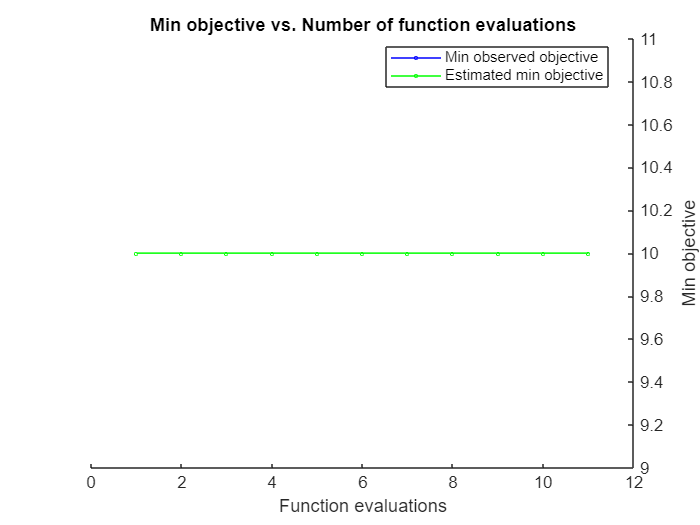

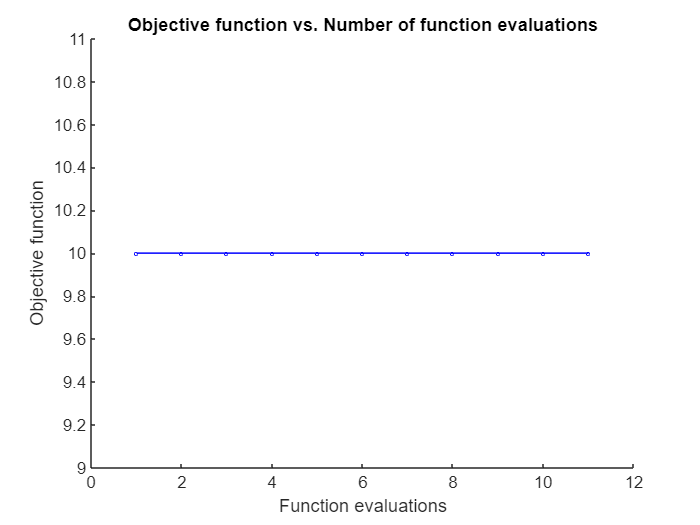

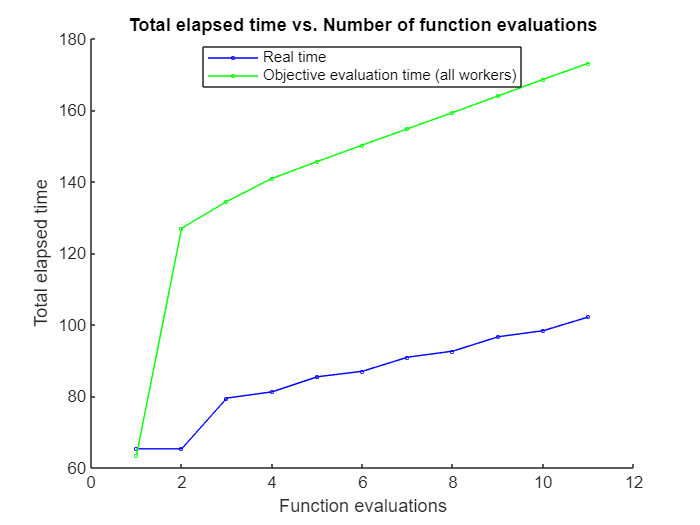

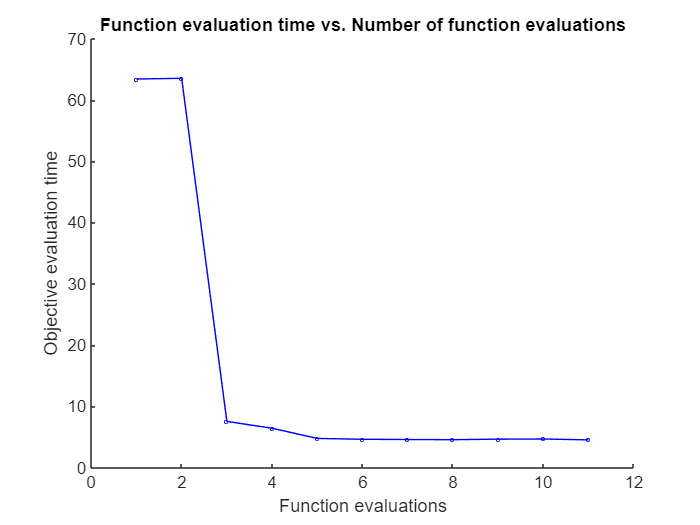

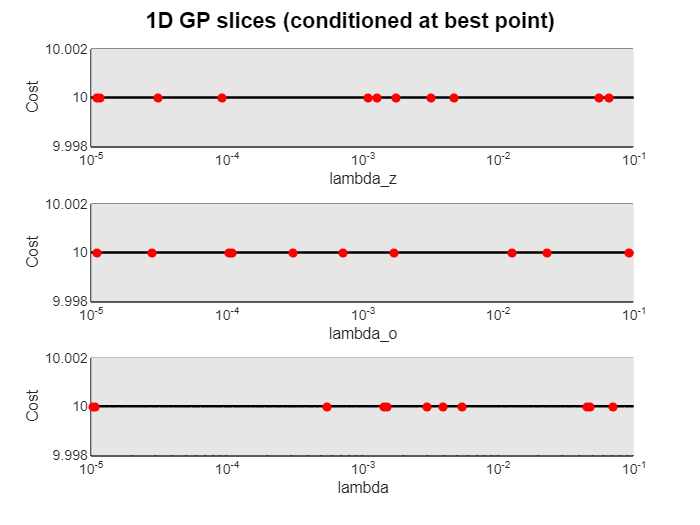

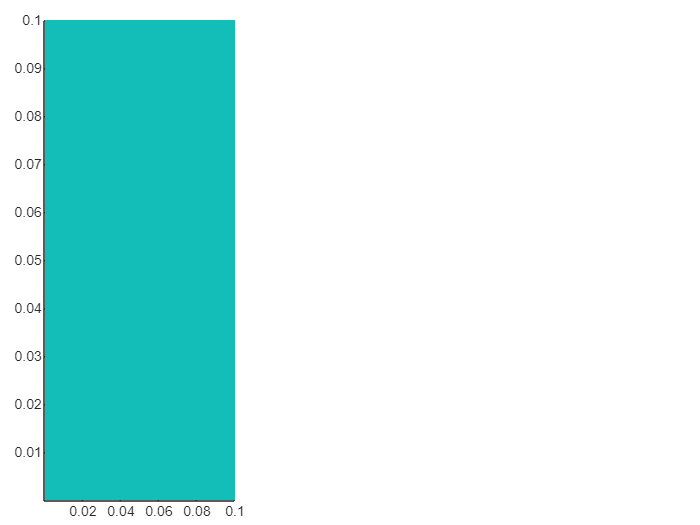

The error message follows:
Limits must be a 2-element vector of increasing numeric values.


limits = vertcat(optimization_variables.Range);
lb = log10(limits(:, 1).');
ub = log10(limits(:, 2).');

NumSeedPoints = 2*p.NumWorkers;
Xlhs = lhsdesign(NumSeedPoints, nVars);
Xinit = 10 .^ bsxfun(@plus, lb, bsxfun(@times, (ub-lb), Xlhs));
Xinit = array2table(Xinit, 'VariableNames', {optimization_variables.Name});

results = bayesopt(@objective_function, optimization_variables, ...
    'MaxObjectiveEvaluations',   10*p.NumWorkers, ...
    'InitialX',                  Xinit, ...
    'AcquisitionFunctionName',   'expected-improvement-plus', ...
    'IsObjectiveDeterministic',  true, ...
    'UseParallel',               true, ...
    'Verbose',                   1, ...
    'PlotFcn',                   {@plotMinObjective, ...
                                  @plotObjective, ...
                                  @plotElapsedTime, ...
                                  @plotObjectiveEvaluationTime, ...
                                  @plotSurrogate} ...
);

## Reconstruct GP model

Retrieve bayesian optimization results

X = results.XTrace;
Y = results.ObjectiveTrace;
[Y, idx] = sort(Y, 'ascend'); % Sort by cost function
X = X(idx, :); 
varNames = {results.VariableDescriptions.Name};
sorted_Trace = [X table(Y, 'VariableNames', {'Cost'})]

Fit gaussian process

gp = fitrgp(X, Y, ...
    'Standardize', true, ...
    'KernelFunction', 'ardsquaredexponential');

## Plot GP

Plot fitted gaussian process

plotGP(gp, results, 'qF', 'qw')

## Sensitivity analysis

Global (trained kernel length scales)

A smaller lenght scale denotes a more important variable

lengthScales = gpGlobalSensitivity(gp)

Local (model gradient)

x_eval = table2array(X(1, :));
[gradMu, gradSigma2] = gpLocalSensitivity(gp, x_eval)